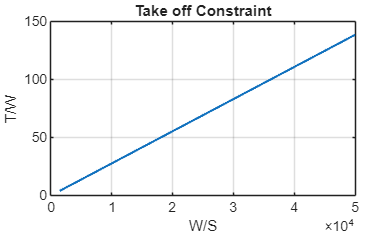

clc; clear; 
%Loading data calculated before
params = readtable("Key_Param_recording.csv", 'ReadRowNames', true);
W_0 = params{"W_0_guess","Value"};
W_e = params{"W_e","Value"};
W_f = params{"W_f","Value"};
V_cruise = params{"V_cruise","Value"};
V_loiter = params{"V_loiter","Value"};
LD_max = params{"LD_max","Value"};%??? where my this value come from?
LD_cruise = params{"LD_cruise","Value"};%??? where my this value come from?
K_LD = params{"K_LD","Value"};
loiter_alt_ft = params{"loiter_alt_ft","Value"};
cruise_alt_offset_ft = params{"cruise_alt_offset_ft","Value"};
abs_ceiling_ft = params{"abs_ceiling_ft","Value"};
M_cruise = params{"M_cruise","Value"};
Swet_Sref = params{"Swet_Sref","Value"};
AR = params{"AR","Value"};
R_cruise_nmi =params{"R_cruise_nmi","Value"};
R_alt_km =params{"R_alt_km","Value"};
Wr_taxi_takeoff = params{"Wr_taxi_takeoff","Value"}; 
Wr_climb =params{"Wr_climb","Value"};
Wr_cruise = params{"Wr_cruise","Value"};
Wr_descent =params{"Wr_descent","Value"};
Wr_missed_approach =params{"Wr_missed_approach","Value"};
Wr_cruise_alt=params{"Wr_cruise_alt","Value"};
Wr_loiter=params{"Wr_loiter","Value"};
Wr_land_taxi =params{"Wr_land_taxi","Value"};
L_runway = params{"L_runway","Value"};
S_ref = params{"S_ref","Value"};
g0 = 9.81;
gamma_air = 1.4;
R = 287.05;
rho_SL = 1.225;% Atmosphere at sea level
N2psf = 1/47.88;
ft2m = 0.3048;   
%===============================================================
%Constrain diagram - reselect e and CD0 here
e = params{"Oswald_efficiency_factor","Value"}; % Oswald efficiency factor - 0.7-0.85
CD0 =params{"CD0","Value"}; % Zero-lift drag coefficient
k = 1/(pi*e*AR);
% Wing loading range (N/m^2)
Wing_loading_series = linspace( 1500,50000, 1000);
%%Take-off Constraint
CLmax_TakeOff = 2.0;% ?
sigma_TakeOff = 1.0;% Density ratio - take off same to sealevel assumption made
TOP = 180; %?
TW_TakeOff = Wing_loading_series ./ (sigma_TakeOff * CLmax_TakeOff * TOP);
% take off figure - 1st constrain diagram
figure;
plot(Wing_loading_series, TW_TakeOff, 'LineWidth', 1.5);
xlabel('W/S');
ylabel('T/W');
title('Take off Constraint');
grid on;

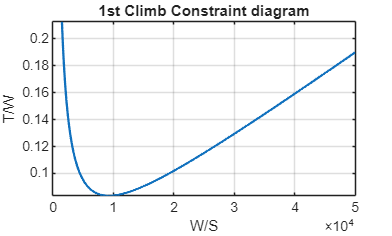


%%1st Climb Constraint
rho_climb = rho_SL; 
V_climb = params{"V_climb","Value"};%?
climb_gradient_1st=  params{"climb_gradient_1st","Value"};%?
gamma_1st = asin(climb_gradient_1st);% 2.4% as climb gradient
q_climb_1st = 0.5*rho_climb*V_climb^2;
TW_climb_1st = q_climb_1st*CD0./Wing_loading_series+ k*Wing_loading_series/q_climb_1st + sin(gamma_1st);

figure;
plot(Wing_loading_series, TW_climb_1st, 'LineWidth', 1.5);
xlabel(' W/S ');
ylabel('T/W');
title('1st Climb Constraint diagram');
grid on;

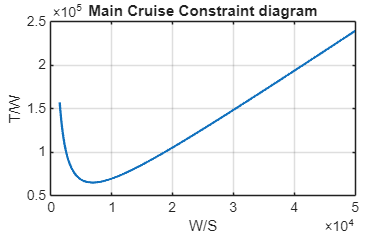


%% Cruise Constraint
[T_cruise, a_cruise, P_cruise, rho_cruise] = atmosisa((abs_ceiling_ft-cruise_alt_offset_ft)*ft2m);
q_cruise = 0.5*rho_cruise*V_cruise^2;

% Weight fraction at cruise
Wcruise_W0_ratio = W_0*Wr_taxi_takeoff*Wr_climb;
alpha_cruise = params{"alpha_cruise","Value"};% Available thrust / sea-level static thrust
TW_cruise = Wcruise_W0_ratio/alpha_cruise * (q_cruise*CD0./Wing_loading_series + k*Wing_loading_series/q_cruise);

figure;
plot(Wing_loading_series, TW_cruise, 'LineWidth', 1.5);
xlabel('W/S');
ylabel('T/W');
title('Main Cruise Constraint diagram');
grid on;

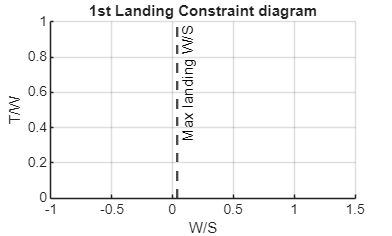


%%1st Landing Constraint
CLmax_Landing = params{"CLmax_Landing","Value"}; %reasonable random
Vstall_Landing = params{"Vstall_Landing","Value"};%reasonable random - 70 vscode give me lmao
rho_Landing = rho_SL;
WLanding_W0_1st = W_0 * Wr_taxi_takeoff *Wr_climb * Wr_cruise;
Wing_loading_max_Landing_1st = 0.5*rho_Landing*Vstall_Landing^2*CLmax_Landing / WLanding_W0_1st;

figure;
xline(Wing_loading_max_Landing_1st, '--k', 'Max landing W/S', ...
    'LineWidth', 1.5);
xlabel('W/S');
ylabel('T/W');
title('1st Landing Constraint diagram');
grid on;

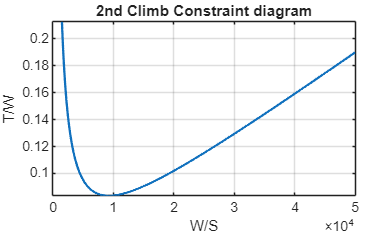


%%2nd Climb Constraint
rho_climb = rho_SL; 
V_climb = params{"V_climb","Value"};%?
climb_gradient_2nd=  params{"climb_gradient_2nd","Value"};%?
gamma_2nd = asin(climb_gradient_2nd);% 2.4% as climb gradient
q_climb = 0.5*rho_climb*V_climb^2;
TW_climb = q_climb*CD0./Wing_loading_series+ k*Wing_loading_series/q_climb + sin(gamma_2nd);

figure;
plot(Wing_loading_series, TW_climb, 'LineWidth', 1.5);
xlabel(' W/S ');
ylabel('T/W');
title('2nd Climb Constraint diagram');
grid on;

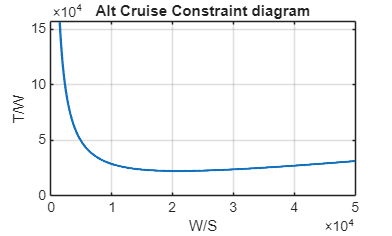


%% alternative airport 2nd cruise Constraint
h_loiter = loiter_alt_ft*ft2m;
[T_alt, a_alt, P_alt, rho_alt] = atmosisa(h_loiter);
V_alt = V_cruise;
q_alt = 0.5*rho_alt*V_alt^2;

% Weight fraction at cruise
Walt_W0_ratio = W_0*Wr_taxi_takeoff*Wr_climb*Wr_cruise*Wr_descent*Wr_missed_approach;
alpha_alt = params{"alpha_alt","Value"};% Available thrust / sea-level static thrust
TW_alt = Walt_W0_ratio/alpha_alt * (q_alt*CD0./Wing_loading_series + k*Wing_loading_series/q_alt);

figure;
plot(Wing_loading_series, TW_alt, 'LineWidth', 1.5);
xlabel('W/S');
ylabel('T/W');
title('Alt Cruise Constraint diagram');
grid on;

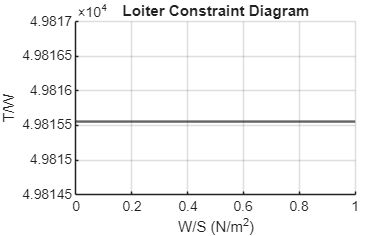


%% Loiter Constraint
t_loiter = 45*60; %s
rho_loiter = rho_alt;     
LD_loiter = LD_max; 
Wloiter_W0 = W_0 * Wr_taxi_takeoff *Wr_climb * Wr_cruise * Wr_missed_approach*Wr_cruise_alt;  
alpha_loiter =  params{"alpha_loiter","Value"}; 
TW_loiter = Wloiter_W0 / (alpha_loiter * LD_loiter);

figure;
yline(TW_loiter, 'LineWidth', 1.5);
xlabel('W/S (N/m^2)');
ylabel('T/W');
title('Loiter Constraint Diagram');
grid on;

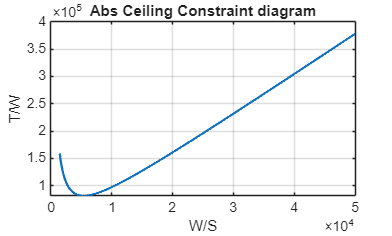


%% Ceiling Constraint
h_ceiling = abs_ceiling_ft * ft2m; 
[T_ceiling, a_ceiling, P_ceiling, rho_ceiling] = atmosisa(h_ceiling);
V_ceiling = V_cruise;% assumption
ROC = params{"ROC","Value"};%??? 0 for now
Wceiling_W0_ratio =Wcruise_W0_ratio;  % assumpti;  % Absolute ceiling approximation
alpha_ceiling = params{"alpha_ceiling","Value"};% Same to above but to ceiling
q_ceiling = 0.5*rho_ceiling*V_ceiling^2;
TW_ceiling = Wceiling_W0_ratio/alpha_ceiling * (q_ceiling*CD0./Wing_loading_series + k*Wing_loading_series/q_ceiling + ROC/V_ceiling);

figure;
plot(Wing_loading_series, TW_ceiling, 'LineWidth', 1.5);
xlabel('W/S');
ylabel('T/W');
title('Abs Ceiling Constraint diagram');
grid on;

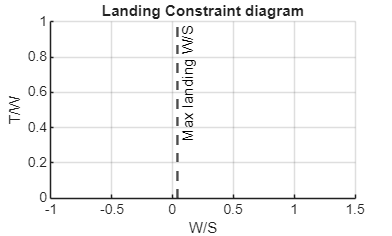



%%Landing Constraint
CLmax_Landing = params{"CLmax_Landing","Value"}; %reasonable random
Vstall_Landing = params{"Vstall_Landing","Value"};%reasonable random - 70 vscode give me lmao
rho_Landing = rho_SL;
WLanding_W0 = W_0 * Wr_taxi_takeoff *Wr_climb * Wr_cruise * Wr_missed_approach*Wr_cruise_alt*Wr_loiter; 
Wing_loading_max_Landing = 0.5*rho_Landing*Vstall_Landing^2*CLmax_Landing / WLanding_W0;

figure;
xline(Wing_loading_max_Landing, '--k', 'Max landing W/S', ...
    'LineWidth', 1.5);
xlabel('W/S');
ylabel('T/W');
title('Landing Constraint diagram');
grid on;

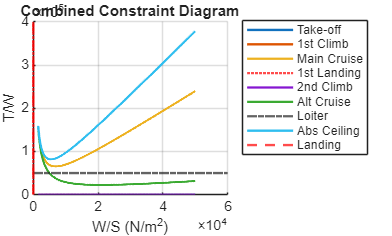


%==============================================================================
%% Constraint diagram - single plot
figure; hold on; grid on;

plot(Wing_loading_series, TW_TakeOff, 'LineWidth', 1.5, 'DisplayName', 'Take-off');
plot(Wing_loading_series, TW_climb_1st, 'LineWidth', 1.5, 'DisplayName', '1st Climb');
plot(Wing_loading_series, TW_cruise, 'LineWidth', 1.5, 'DisplayName', 'Main Cruise');
xline(Wing_loading_max_Landing_1st, ':r', 'LineWidth', 1.5, 'DisplayName', '1st Landing');
plot(Wing_loading_series, TW_climb, 'LineWidth', 1.5, 'DisplayName', '2nd Climb');
plot(Wing_loading_series, TW_alt, 'LineWidth', 1.5, 'DisplayName', 'Alt Cruise');
yline(TW_loiter, '-.', 'LineWidth', 1.5, 'DisplayName', 'Loiter');
plot(Wing_loading_series, TW_ceiling, 'LineWidth', 1.5, 'DisplayName', 'Abs Ceiling');
xline(Wing_loading_max_Landing, '--r', 'LineWidth', 1.5, 'DisplayName', 'Landing');

xlabel('W/S (N/m^2)');
ylabel('T/W');
title('Combined Constraint Diagram');
legend('Location', 'northeastoutside');
hold off;

%===============================================================
%stall calculation
% Cl calculation
q= 0.5 *rho_cruise * V_cruise^2;
Wing_loading = (W_0 - W_f*(1-Wr_taxi_takeoff*Wr_climb)) *g0 / S_ref

Wing_loading = 4.6084e+03

%Wing_loading_max= 0.5 *rho * V_stall^2*Cl_max_set;
Cl_max= Wing_loading / q

Cl_max = 0.4476

%thrust_weight_ratio_min = Wing_loading_max / (Air_density_ratio*TOP)%empirical take-off parameter (TOP) method

% Aspect ratio - jet transporrt wide body (7.5 -10) adopted 9 for smaller wing span and remain in Code E
a_AR =  params{"a_AR","Value"};
c_AR =  params{"c_AR","Value"};
M_max  = M_cruise;
AR_cal = a_AR * M_max^c_AR;
b = sqrt(AR * S_ref)

b = 73.4847

% Taper Ratio - lambda calculation (C_tip / C_root)
lambda =  params{"lambda","Value"};% 0.45 from ppt
c_root = 2* S_ref /(b *(1+ lambda));
c_tip = c_root * lambda;
%sweep - subsonic use historical trend will be enough
Sweep_LE =  params{"Sweep_LE","Value"}; % deg, ish 35 from reading using eye historical trend line double check later!!!
% As CL_max = 0.9*clmax*cos(Sweep_c4), this from ppt clear wing --> take off speed
Sweep_c4 = atand(tand(Sweep_LE) - (1/AR)*(1-lambda)/(1+lambda));
CL_max = 0.9*Cl_max*cosd(Sweep_c4)

CL_max = 0.3365


%Thickness Ratio????

%twist angle choice- given -3 deg
twist_angle = params{"twist_angle","Value"};
Twist_along_wing_hold = linspace(0,1,51); % 0 = root, 1 = tip
twist = twist_angle*Twist_along_wing_hold; % linear distribution, deg

% Incidence angle -?????
beta = sqrt(1-M_cruise^2);  eta = 0.95;
Lam_half = atand(tand(Sweep_c4) - (4/AR)*0.25*(1-lambda)/(1+lambda));
CLa  = 2*pi*AR/(2+sqrt(4+(AR*beta/eta)^2*(1+tand(Lam_half)^2/beta^2)));
CLa_deg = CLa*pi/180;                  % per degree
alpha0L = -3;                          % deg, PLACEHOLDER: from aerofoil data
incidence = Cl_max/CLa_deg + alpha0L;  % fuselage level at cruise


% dihedral -Subsonic swept wing
% low 3-7, mid -2-2, high -5- -2   need to check engine first no idea rn
% use low here 

% High-lift devices need to decide later 
% Clean wing alr had above C_Lmax --> 
Sweep_HL=-25;%idk j random number
S_flapped =0.675* S_ref;% assumed random no refernce at all 
delta_c_lmax = 1.3; %slotted, random choice
delta_C_Lmax = 0.9 * delta_c_lmax * (S_flapped / S_ref) * cosd(Sweep_HL);
CL_max_total =CL_max + delta_C_Lmax

CL_max_total = 1.0523

W_landing =W_0-W_f*(1-0.01);%0.01 fuel margin too lazy to cite sorry
Wing_loading_landing= W_landing *g0/S_ref;
V_takeoff =90.02;% not defined yet, m/s
CL_max_required = 2* Wing_loading_landing / (1.225*(V_takeoff/1.23)^2)

CL_max_required = 0.9035